clear all

Dimension (along both direction):

N = 4;

Set up **Hilbert Matrix**:

H = bsxfun(@plus,[1:N]',0:N-1)      % not H! only middle product

H =      1     2     3     4
     2     3     4     5
     3     4     5     6
     4     5     6     7


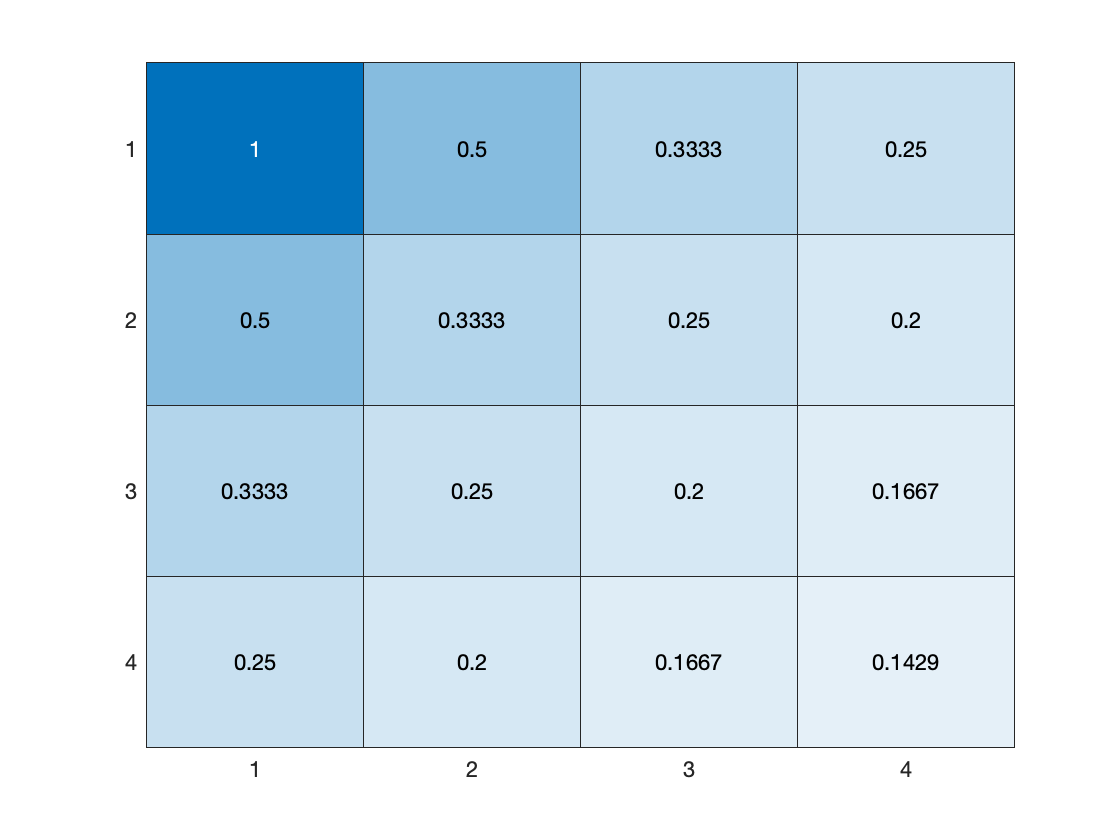

H = 1./H; heatmap(H);               % Element-wise inversion
colorbar off

Attept to invert:

iH = inv(H)

iH = 	1.0e+03 *

    0.0160   -0.1200    0.2400   -0.1400
   -0.1200    1.2000   -2.7000    1.6800
    0.2400   -2.7000    6.4800   -4.2000
   -0.1400    1.6800   -4.2000    2.8000


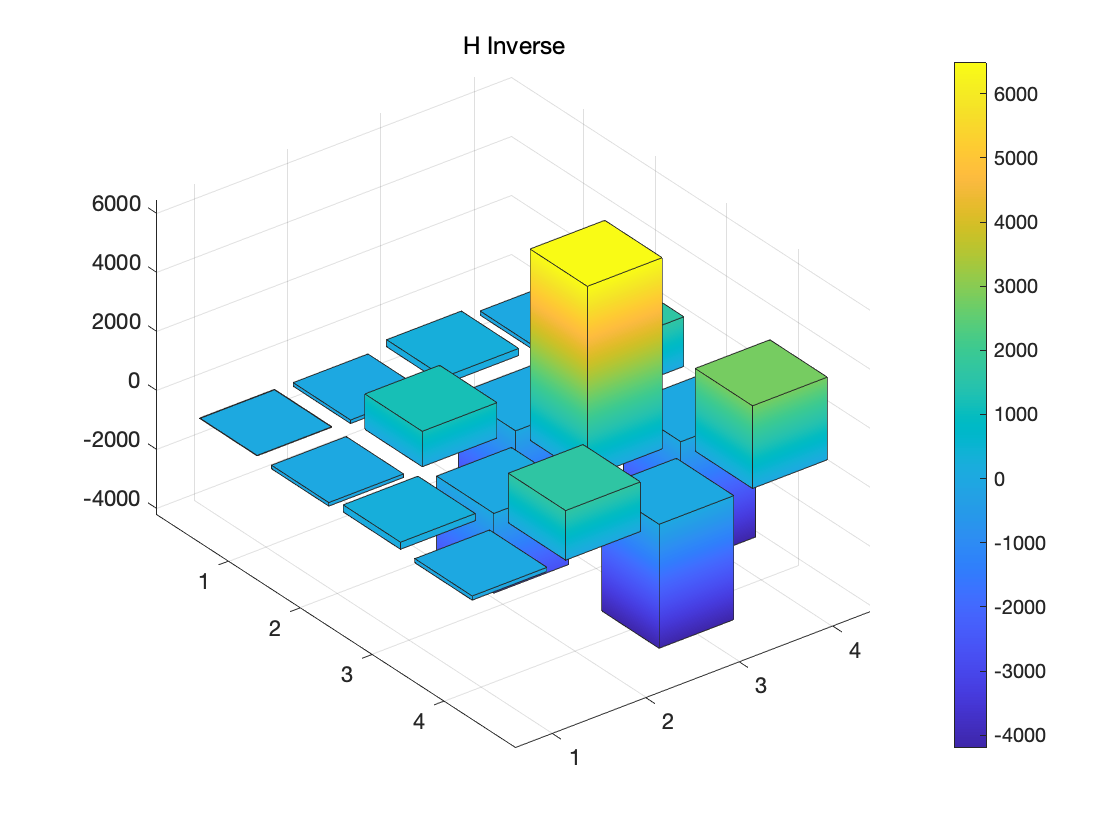

b = bar3(iH); title("H Inverse"); colorbar
for k = 1:length(b)
    zdata = b(k).ZData;
    b(k).CData = zdata;
    b(k).FaceColor = 'interp';      % interpolating color with height
end

cond(H)  % condition number

ans = 1.5514e+04

Note: Using maps throughout doc to get better visuals